# Demo_SPEN_unaliasing by deconvolution

This document contains the simulation of SPEN unaliasing procedure.

## Contents

- Load the data

- k space simulation including conventional (EPI k space) and (SPEN k space)

- Unaliasing SPEN images by deconvolution

## Load the data

Two types of data are provided:

(1) Brain T1 image: **Data from: T1-weighted in vivo human whole brain MRI dataset with an ultrahigh isotropic resolution of 250 μm, Lüsebrink F, Sciarra A, Mattern H, Yakupov R, Speck O  **Date Published: March 10, 2017 DOI: https://doi.org/10.5061/dryad.38s74

(2) Shepp-Logan head phantom image.

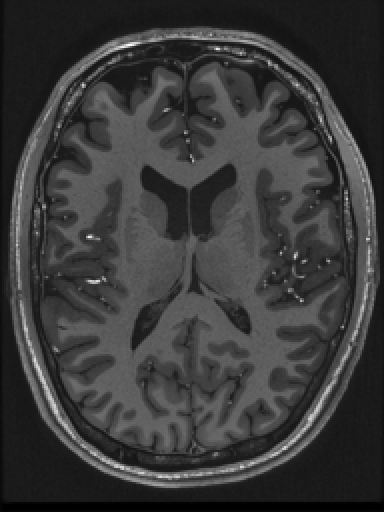

clc; clear; close all;
toolpath=genpath('tool');
addpath(toolpath);
addpath('data');
addpath('src');

%Choose either one type of data
% brain image
load im_brain_highres.mat
figure; ismrm_imshow(imresize(im,[256 192]))

% phantom image
% im = phantom(4096);
% figure();ismrm_imshow(imresize(im,[192 192]))

## k-space simulation

First generate a large k space from "high-resolution" image, then we sample from this "full" k space with different subsampling factor, here we use Nacc=[1 2 3 4]

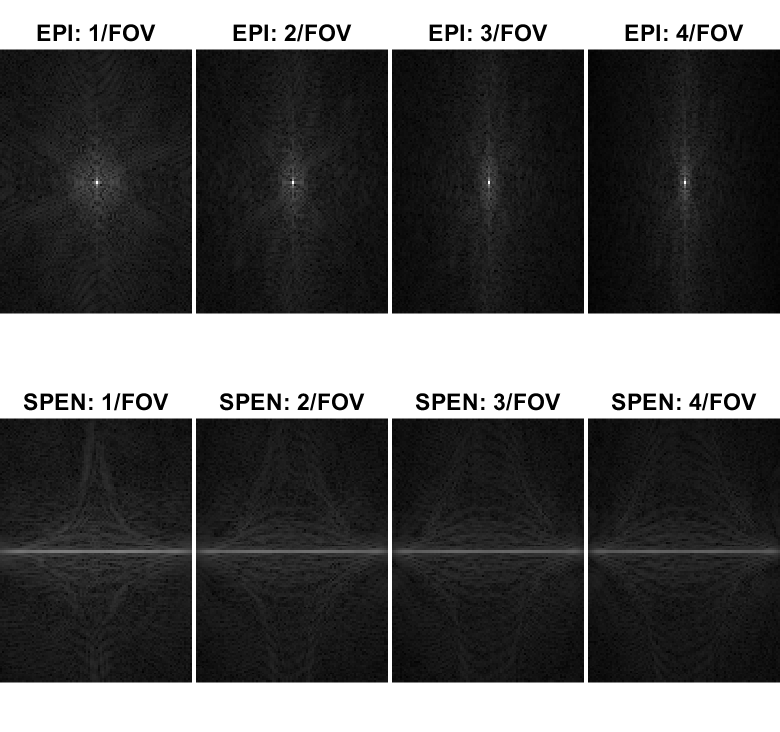

%Parameters setting
[sx,sy] = size(im);
Nacc=[1 2 3 4];
Nk=96;
FOV=200;
deltak=Nacc*1/FOV;
Q=Nacc*Nk/2/FOV^2;
ysource = (-sy/2:sy/2-1)*FOV/sy;
k_EPI_full = fft2r2k(im);
k_SPEN_full = fft2r2k(bsxfun(@times,im,permute(exp(1i*2*pi*Q.'*ysource.^2),[3 2 1])));

k_EPI=zeros(Nk*sx/sy,Nk,length(Nacc));
k_SPEN=zeros(Nk*sx/sy,Nk,length(Nacc));
txtarray_EPI=cell(1,length(Nacc));
txtarray_SPEN=cell(1,length(Nacc));
for m=1:length(Nacc)
    k_EPI(:,:,m)=crop(k_EPI_full(:,(sy/2+1)+(-Nk/2*Nacc(m):Nacc(m):(Nk/2-1)*Nacc(m))),[Nk*sx/sy,Nk]);    
    k_SPEN(:,:,m)=crop(k_SPEN_full(:,(sy/2+1)+(-Nk/2*Nacc(m):Nacc(m):(Nk/2-1)*Nacc(m)),m),[Nk*sx/sy,Nk]);
    txtarray_EPI{m}=['EPI: ',num2str(m),'/FOV'];
    txtarray_SPEN{m}=['SPEN: ',num2str(m),'/FOV'];
end

im_EPI=fft2k2r(k_EPI);
im_SPEN=fft2k2r(k_SPEN);
figure();ismrm_imshow(abs(cat(3,k_EPI,k_SPEN)).^(1/3),[],[2,length(Nacc)],cat(2,txtarray_EPI,txtarray_SPEN));

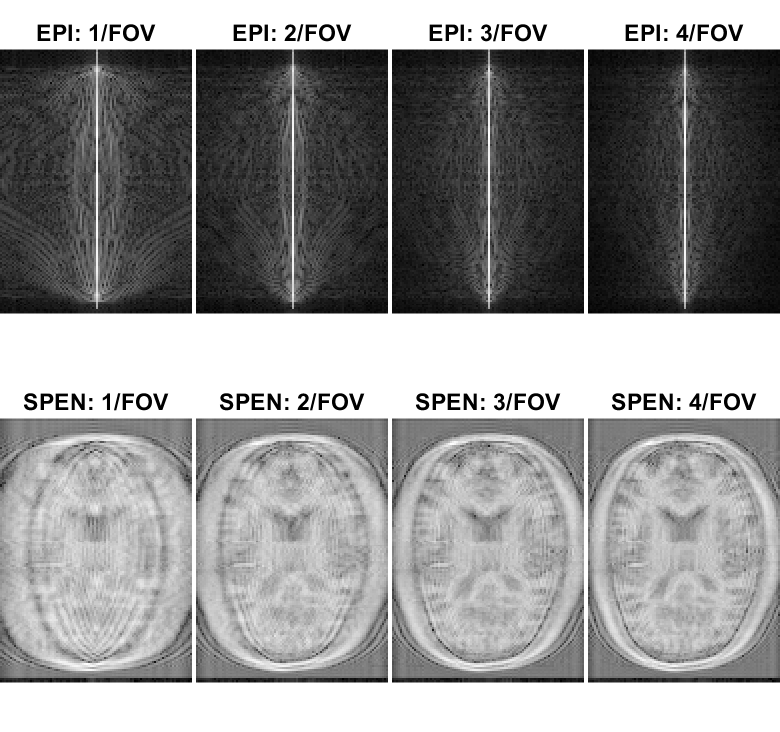

figure();ismrm_imshow(abs(fftk2r(cat(3,k_EPI,k_SPEN),[],1)).^(1/3),0,[2,length(Nacc)],cat(2,txtarray_EPI,txtarray_SPEN));

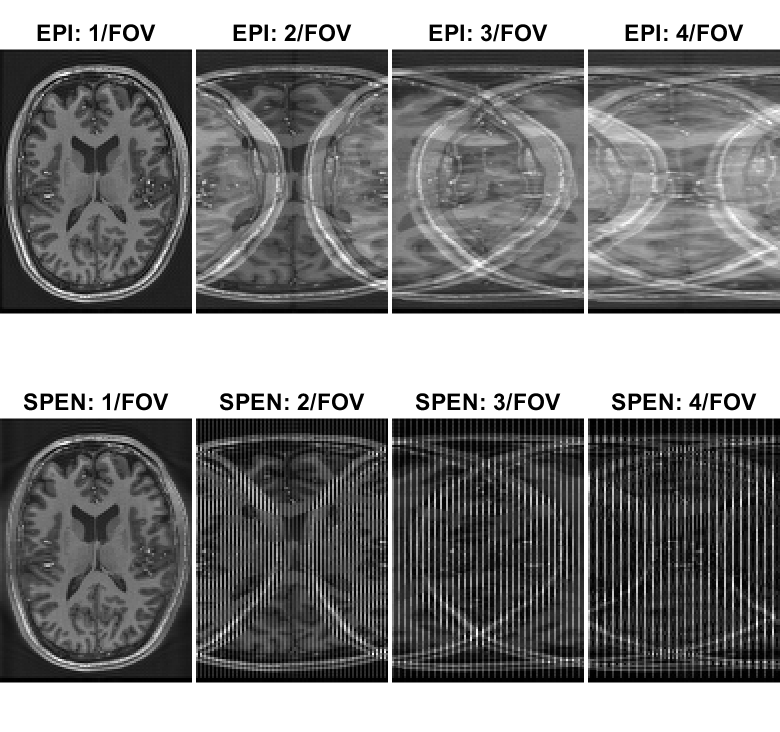

figure();ismrm_imshow(abs(cat(3,im_EPI,im_SPEN)),0,[2,length(Nacc)],cat(2,txtarray_EPI,txtarray_SPEN));

## In imaging space, we apply a quadratic phase demodulation, it gives a deconvolution in k-space

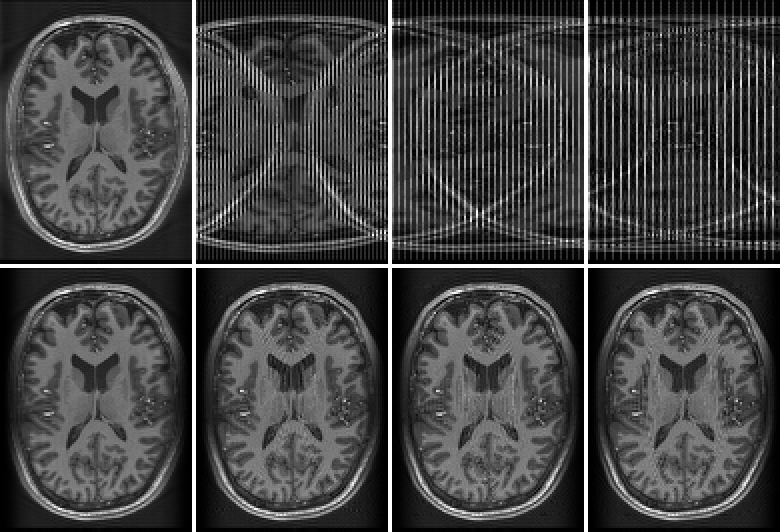

im_SPEN_unaliasing=zeros(size(k_SPEN));
for m=1:length(Nacc)
    Nx=Nk*sx/sy;
    Ny=Nk*Nacc(m);
    k_SPEN_zerofill=zeros(Nx,Ny);
    k_SPEN_zerofill(:,1:Nacc(m):end)=k_SPEN(:,:,m);
    im=fft2k2r(k_SPEN_zerofill);
    y=linspace(-FOV/2,FOV/2,Ny);
    ph=wurst(20,Ny).*exp(1i*2*pi*Q(m)*y.^2);
    im_phdemodulation=im.*conj(ph);
    k_deconvolution=fft2r2k(im_phdemodulation);
    im_SPEN_unaliasing(:,:,m)=fft2k2r(crop(k_deconvolution,[Nx,Nk]));  
end
figure();ismrm_imshow(abs(cat(3,im_SPEN,im_SPEN_unaliasing)),0,[2 length(Nacc)]);